# Environment Initialisation

close all;
clearvars;
clc;

addpath("./functions/");
ds_path = "./datasets/";

# Model Initialisation

% 20s pre-jump dataset is imported
data_tt = readtimetable(ds_path + "dataset_regular_20s.csv");

% Model parametres
features = {@(x) median(x, 1)};
feature_labels = ["median"];

slow_vars = ["prc_iron_feed", "prc_silica_feed", ...
                    "prc_iron_concentrate", "prc_silica_concentrate"];
input_vars = data_tt.Properties.VariableNames; % CHANGE THIS!!!
output_vars = "prc_silica_concentrate";
input_memory = 4; % CHANGE THIS!!!
pred_horizon = 1; % Must be >=1 to respect causality

% X_init/Y_init returned as a table in order to preserve feature names 
% (timestamps are no longer important)
[X_init, Y_init] = init_dataset(data_tt, input_vars, output_vars, ...
                                input_memory, pred_horizon, features, feature_labels);


% Initial model trained on this information
% Calling the function will give optimal model based on Q2 and R2

X = X_init; % All variables are lagged and kept, but your model has to filter out some of them!!!
Y = Y_init;
% Initialization of PLS model
max_n_components = 10;
variable_names = Var_name(X, Y, max_n_components, max_n_components);
model = pls_model_initialization(X, Y, variable_names,  max_n_components);
unused_vars = [];
for var=input_vars
    if ~any(startsWith(model.variable_names, var))
        unused_vars = [unused_vars var];
    end
end
input_vars_filt = setdiff(input_vars, unused_vars);


# Online Estimation

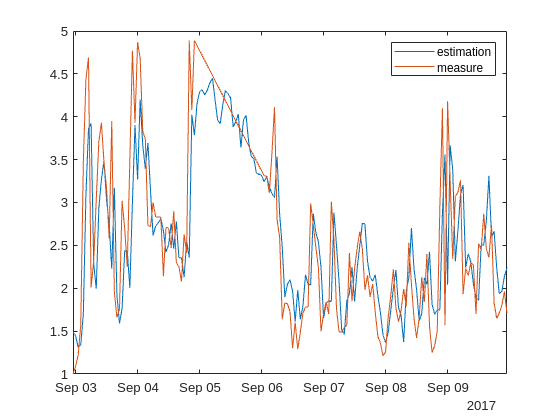

% 20s post-jump dataset stream is created
stream_idx = find(data_tt.Time >= datetime(2017, 06, 15), 1);

% Recalibration parametres
perf = false;
N_trn = 24*7;
Q2_thr = 0.2;
T_recal = 1;

% Resampling parametres
fast_counter = 0;
slow_counter = 0;
resample_ratio = 180;
fast_input_vars = setdiff(input_vars_filt, slow_vars);
slow_input_vars = intersect(input_vars_filt, slow_vars);
fast_buffer = array2table(zeros(resample_ratio, numel(fast_input_vars)), ...
                            "VariableNames", fast_input_vars);

% Execution dataset init
input_width = numel(features)*numel(fast_input_vars) + numel(slow_input_vars);
input_dset = array2table(zeros(0, input_width));

output_width = numel(output_vars);
output_dset = array2timetable(zeros(0, 2*output_width), ...
    "TimeStep", hours(1), ...
    "StartTime", data_tt.Time(stream_idx), ...
    "VariableNames", [output_vars+"_hat_t+"+string(pred_horizon), ...
        output_vars+"_t+"+string(pred_horizon)]);
beta_timetable = array2timetable(zeros(0, numel(model.B)), ...
    "TimeStep", hours(1), ...
    "StartTime", data_tt.Time(stream_idx), ...
    "VariableNames", ["Bias", string(model.variable_names)]);

mem_init_flag = false;

figure();

%#ok<*AGROW>
%#ok<*SAGROW>
while stream_idx <= height(data_tt)
    % Time stamp for estimation-measurement synchronisation
    if fast_counter==0
        time_stamp = data_tt.Time(stream_idx);
    end

    % Append to fast_input_vars buffer
    fast_counter = fast_counter + 1;
    fast_buffer(fast_counter, :) ...
        = timetable2table(data_tt(stream_idx, fast_input_vars), ...
            "ConvertRowTimes", false);
    
    % Fast variables' buffer is big enough (an hour has passed)
    if fast_counter == resample_ratio
        fast_counter = 0;
        slow_counter = slow_counter + 1;

        % Record latest available measure
        if size(output_dset, 1) >= pred_horizon
            output_dset(time_stamp, output_vars+"_t+"+string(pred_horizon)) ...
                = data_tt(stream_idx, output_vars);

            % Plot estimation vs measure
            plot(output_dset.Time, output_dset{:,:});
            xlim([time_stamp-hours(N_trn), time_stamp]);
            legend(["estimation", "measure"]);
            drawnow();
        end

        % Model update logic
        if (size(output_dset, 1)-pred_horizon) >= N_trn
            % Check if a model update is required
            upd_req = upd_cond(perf, slow_counter, ...
                output_dset(end-pred_horizon-N_trn+1:end-pred_horizon, :), ...
                Q2_thr, T_recal);
    
            if upd_req
                % Generate recalibration dataset
                X = time_lag(input_dset(1:N_trn+input_memory,:), input_memory);
                Y = timetable2table(output_dset(end-pred_horizon-N_trn+1:end-pred_horizon, ...
                            output_vars+"_t+"+string(pred_horizon)), ...
                        "ConvertRowTimes", false);
                model = update_model(model,X,Y);

                % Reset slow counter
                slow_counter = 0;
            end
            % Remove oldest input
            input_dset(1,:) = [];
        end

        % Generate current input
        current_input = [heuristic_encoding(fast_buffer, resample_ratio, ...
                                features, feature_labels), ...
                            timetable2table(data_tt(stream_idx, slow_input_vars), ...
                                "ConvertRowTimes", false)];
        current_input.Properties.VariableNames ...
            = current_input.Properties.VariableNames;  
        
        % Placeholder memory init
        if ~mem_init_flag
            input_dset.Properties.VariableNames = current_input.Properties.VariableNames;
            for mem_idx=1:input_memory
                input_dset = [input_dset; current_input];
            end
            mem_init_flag = true;
        end

        input_dset = [input_dset; current_input];
        
        % Create time-lagged input
        X = time_lag(input_dset(end-input_memory:end,:), input_memory);

        % Call model: Y_hat = model(X)
        beta_timetable{time_stamp,:} = model.B';
        Y_hat = call_model(model, X);
        Y_hat(Y_hat<0) = 0; Y_hat(Y_hat>100) = 100; % Percentual value saturation
        current_prediction = array2table([Y_hat, NaN(size(Y_hat))], ...
            "VariableNames",  output_dset.Properties.VariableNames);
        output_dset(time_stamp+hours(pred_horizon), :) = current_prediction;
    end
    
    % Move to the next sample
    stream_idx = stream_idx + 1;
end

# Results Analysis

output_dset(any(ismissing(output_dset), 2), :) = [];
Y = output_dset{:,output_vars+"_t+"+string(pred_horizon)};
Y_hat = output_dset{:,output_vars+"_hat_t+"+string(pred_horizon)};
Q2 = 1 - sum((Y-Y_hat).^2, 1) ./ sum((Y-mean(Y,1)).^2, 1)

Q2 = 0.5294

RMSE = rms(Y-Y_hat, 1)

RMSE = 0.7312

MAE = mean(abs(Y-Y_hat))

MAE = 0.5075

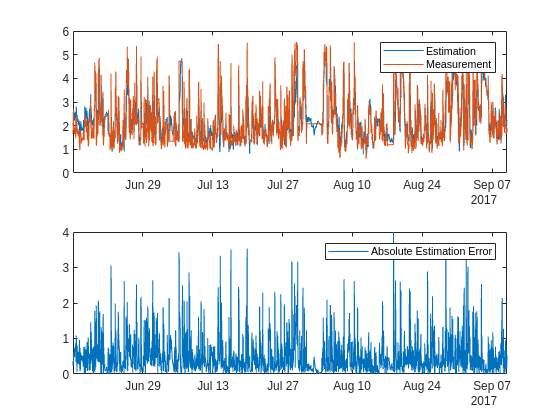

figure();
tiledlayout(2,1);
ax(1) = nexttile();
plot(output_dset.Time, output_dset{:,:});
legend(["Estimation", "Measurement"]);
ax(2) = nexttile();
plot(output_dset.Time, abs(output_dset{:,1}-output_dset{:,2}));
legend("Absolute Estimation Error")
linkaxes(ax, "x"); xlim("tight");

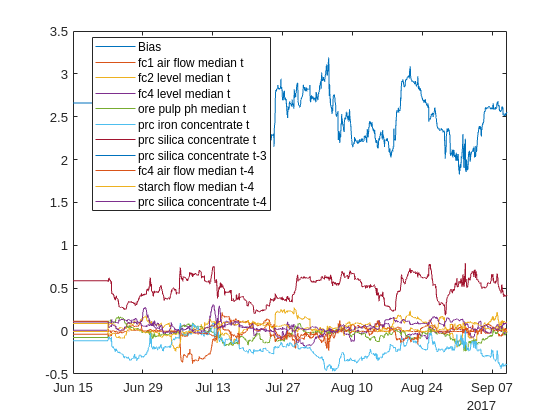


figure();
h = plot(beta_timetable.Time, beta_timetable{:,:});
xlim("tight");

for line_idx=1:numel(h)
    h(line_idx).DataTipTemplate.DataTipRows(end+1) ...
        = dataTipTextRow('Variable', ...
            repmat(strrep(beta_timetable.Properties.VariableNames{line_idx}, "_", " "), height(beta_timetable), 1));
end

legend(strrep(beta_timetable.Properties.VariableNames, "_", " "), ...
    "Location", "best");